clear; clc;
stats = readtable('bball_stats.xlsx');
playerinfo = readtable('bball_players.xlsx');

## Construct full names

firstname = playerinfo.useFirst% Extract useFirst

firstname = 5061×1 cell 배열
    {'Alaa'    }
    {'Kareem'  }
    {'Mahdi'   }
    {'Mahmoud' }
    {'Tariq'   }
    {'Zaid'    }
    {'Forest'  }
    {'John'    }
    {'Alex'    }
    {'Mark'    }
    {'Alvan'   }
    {'George'  }
    {'Hassan'  }
    {'Michael' }
    {'Rafael'  }
    {'Jeff'    }
    {'Maurice' }
    {'Mark'    }
    {'Henry'   }
    {'Mark'    }
    {'Gary'    }
    {'Cole'    }
    {'LaMarcus'}
    {'Cory'    }
    {'Courtney'}
    {'Gary'    }
    {'Victor'  }
    {'Jerome'  }
    {'Lavoy'   }
    {'Lucius'  }


idx = ismissing(firstname) % Indexing missing firstnam

idx = 5061×1 logical 배열
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


firstname(idx) = playerinfo.useFirst(idx) % Replace missing data with 'firstName' data

firstname = 5061×1 cell 배열
    {'Alaa'    }
    {'Kareem'  }
    {'Mahdi'   }
    {'Mahmoud' }
    {'Tariq'   }
    {'Zaid'    }
    {'Forest'  }
    {'John'    }
    {'Alex'    }
    {'Mark'    }
    {'Alvan'   }
    {'George'  }
    {'Hassan'  }
    {'Michael' }
    {'Rafael'  }
    {'Jeff'    }
    {'Maurice' }
    {'Mark'    }
    {'Henry'   }
    {'Mark'    }
    {'Gary'    }
    {'Cole'    }
    {'LaMarcus'}
    {'Cory'    }
    {'Courtney'}
    {'Gary'    }
    {'Victor'  }
    {'Jerome'  }
    {'Lavoy'   }
    {'Lucius'  }


 % Check missing in firstname variable

 fullname = strcat(firstname,{' '},playerinfo.useFirst)% Join first and last name with a space in between

fullname = 5061×1 cell 배열
    {'Alaa Alaa'        }
    {'Kareem Kareem'    }
    {'Mahdi Mahdi'      }
    {'Mahmoud Mahmoud'  }
    {'Tariq Tariq'      }
    {'Zaid Zaid'        }
    {'Forest Forest'    }
    {'John John'        }
    {'Alex Alex'        }
    {'Mark Mark'        }
    {'Alvan Alvan'      }
    {'George George'    }
    {'Hassan Hassan'    }
    {'Michael Michael'  }
    {'Rafael Rafael'    }
    {'Jeff Jeff'        }
    {'Maurice Maurice'  }
    {'Mark Mark'        }
    {'Henry Henry'      }
    {'Mark Mark'        }
    {'Gary Gary'        }
    {'Cole Cole'        }
    {'LaMarcus LaMarcus'}
    {'Cory Cory'        }
    {'Courtney Courtney'}
    {'Gary Gary'        }
    {'Victor Victor'    }
    {'Jerome Jerome'    }
    {'Lavoy Lavoy'      }
    {'Lucius Lucius'    }


 playerinfo.Name = fullname% Add fullname to the last column of the table

playerinfo = 5061×27 table
        bioID         useFirst       firstName     middleName         lastName        nameGiven              fullGivenName              nameSuffix               nameNick                 pos      firstseason    lastseason    height    weight          college               collegeOther              birthDate             birthCity         birthState    birthCountry              highSchool                        hsCity                hsState      hsCountry         deathDate         race            Name        
    _____________    ___________    ___________    ___________    ________________    _________    _________________________________    __________    ______________________________    _______    ___________    __________    ______    ______    ____________________    _____________________    ___________________    __________________    __________    ____________    ______________________________    __________________________    ___________    _________    _

## Extract needed player info

height_weight_table = playerinfo(:,{'height','weight'})% Extract height & weight in table

height_weight_table = 5061×2 table
    height    weight
    ______    ______

      82       240  
      85       225  
      74       185  
      73       162  
      78       223  
      81       230  
      75       180  
      75       195  
      77       185  
      83       220  
      81       210  
      77       210  
      76       220  
      70       162  
      79       215  
      79       243  


height_weight_array = playerinfo{:,{'height','weight'}} % EXtract height & weight in array

height_weight_array =     82   240
    85   225
    74   185
    73   162
    78   223
    81   230
    75   180
    75   195
    77   185
    83   220


% Extract playerinfo in table
playerinfo = playerinfo(:,{'bioID','Name','pos','height','weight'})

playerinfo = 5061×5 table
        bioID               Name            pos    height    weight
    _____________    ___________________    ___    ______    ______

    {'abdelal01'}    {'Alaa Alaa'      }    F-C      82       240  
    {'abdulka01'}    {'Kareem Kareem'  }    C        85       225  
    {'abdulma01'}    {'Mahdi Mahdi'    }    G        74       185  
    {'abdulma02'}    {'Mahmoud Mahmoud'}    G        73       162  
    {'abdulta01'}    {'Tariq Tariq'    }    G-F      78       223  
    {'abdulza01'}    {'Zaid Zaid'      }    C-F      81       230  
    {'ablefo01' }    {'Forest Forest'  }    G        75       180  
    {'abramjo01'}    {'John John'      }    F        75       195  
    {'ackeral01'}    {'Alex Alex'      }    G        77       185  
    {'acresma01'}    {'Mark Mark'      }    F-C      83       220  
    {'adamsal01'}    {'Alvan Alvan'    }    C-F      81       210  
    {'adamsge01'}    {'George George'  }    F-G      77       210  
    {'adamsha01'}    

%playerinfo = playerinfo{:,{'bioID','Name','pos','height','weight'}} % This line doesn't work because their types are cell and double.

## Extract regular season statistics for 1990 onward

% Extract 1990 onward
idx = stats >= 1990

'Year'은(는) 인식할 수 없는 테이블 변수 이름입니다.

stats = stats(idx,:)

% Throw away post-season stats
stats(:,(24:end)) = []

## Categorical data

%positions = {'G','G-F','F-G','F','F-C','C-F','C'} 
 positions = {'G','G-F','F-G','F','F-C','C-F','C'} %create 'positions' variable

positions = 1×7 cell 배열
    {'G'}    {'G-F'}    {'F-G'}    {'F'}    {'F-C'}    {'C-F'}    {'C'}


 playerinfo.pos = categorical(playerinfo.pos)% Convert playerinfo.pos to a categorical array 

playerinfo = 5061×27 table
        bioID         useFirst       firstName     middleName         lastName        nameGiven              fullGivenName              nameSuffix               nameNick               pos    firstseason    lastseason    height    weight          college               collegeOther              birthDate             birthCity         birthState    birthCountry              highSchool                        hsCity                hsState      hsCountry         deathDate         race            Name        
    _____________    ___________    ___________    ___________    ________________    _________    _________________________________    __________    ______________________________    ___    ___________    __________    ______    ______    ____________________    _____________________    ___________________    __________________    __________    ____________    ______________________________    __________________________    ___________    _________    _________

 categories(playerinfo.pos)% How many categories?

ans = 12×1 cell 배열
    {'C'    }
    {'C-F'  }
    {'C-F-G'}
    {'C-G'  }
    {'F'    }
    {'F-C'  }
    {'F-C-G'}
    {'F-G'  }
    {'F-G-C'}
    {'G'    }
    {'G-F'  }
    {'G-F-C'}


 playerinfo.pos = categorical(playerinfo.pos,positions)% Force to convert playerinfo.pos to 'positions' categorical array

playerinfo = 5061×27 table
        bioID         useFirst       firstName     middleName         lastName        nameGiven              fullGivenName              nameSuffix               nameNick               pos    firstseason    lastseason    height    weight          college               collegeOther              birthDate             birthCity         birthState    birthCountry              highSchool                        hsCity                hsState      hsCountry         deathDate         race            Name        
    _____________    ___________    ___________    ___________    ________________    _________    _________________________________    __________    ______________________________    ___    ___________    __________    ______    ______    ____________________    _____________________    ___________________    __________________    __________    ____________    ______________________________    __________________________    ___________    _________    _________

 categories(playerinfo.pos)% Now how many categories? It should be seven 

ans = 7×1 cell 배열
    {'G'  }
    {'G-F'}
    {'F-G'}
    {'F'  }
    {'F-C'}
    {'C-F'}
    {'C'  }


## Grouped operations

stats = stats(:,[1 6 8:end])

stats = 10645×18 table
      playerID       GP    minutes    points    oRebounds    dRebounds    rebounds    assists    steals    blocks    turnovers    PF     fgAttempted    fgMade    ftAttempted    ftMade    threeAttempted    threeMade
    _____________    __    _______    ______    _________    _________    ________    _______    ______    ______    _________    ___    ___________    ______    ___________    ______    ______________    _________

    {'abdelal01'}    43      290        135         27           62          89          12         4        12          22        39        116          55           44          25             0               0   
    {'abdulma02'}    67     1505        942         34           87         121         206        55         4         110       149       1009         417           98          84           100              24   
    {'acresma01'}    68     1313        285        140          219         359          25        25        25     

totalstats = grpstats(stats,'playerID','sum')%Total basketball statistics for each player 중요 grpstats

totalstats = 1854×19 table
                   playerID       GroupCount    sum_GP    sum_minutes    sum_points    sum_oRebounds    sum_dRebounds    sum_rebounds    sum_assists    sum_steals    sum_blocks    sum_turnovers    sum_PF    sum_fgAttempted    sum_fgMade    sum_ftAttempted    sum_ftMade    sum_threeAttempted    sum_threeMade
                 _____________    __________    ______    ___________    __________    _____________    _____________    ____________    ___________    __________    __________    _____________    ______    _______________    __________    _______________    __________    __________________    _____________

    abdelal01    {'abdelal01'}         7         256          3200          1465            283              563              846             85             71           70             247           484          1236              620             321              225                 3                  0     
    abdulma02    {'abdulma02'}         9     

idx = totalstats.sum_GP<100 %Remove players who have played fewer than 100 games

idx = 1854×1 logical 배열
   0
   0
   0
   0
   0
   0
   1
   1
   0
   0


totalstats(idx,:) = []

totalstats = 1117×19 table
                   playerID       GroupCount    sum_GP    sum_minutes    sum_points    sum_oRebounds    sum_dRebounds    sum_rebounds    sum_assists    sum_steals    sum_blocks    sum_turnovers    sum_PF    sum_fgAttempted    sum_fgMade    sum_ftAttempted    sum_ftMade    sum_threeAttempted    sum_threeMade
                 _____________    __________    ______    ___________    __________    _____________    _____________    ____________    ___________    __________    __________    _____________    ______    _______________    __________    _______________    __________    __________________    _____________

    abdelal01    {'abdelal01'}         7         256          3200          1465            283              563              846             85             71           70             247           484          1236              620             321              225                 3                  0     
    abdulma02    {'abdulma02'}         9     

totalstats.GroupCount = [];

## Table properties - 주의깊게 보기 

vars = stats.Properties.VariableNames; % Extract the variable names from the table of statistics
totalstats.Properties.VariableNames = vars % Replace the variable names with 'vars' variable

totalstats = 1117×18 table
                   playerID       GP     minutes    points    oRebounds    dRebounds    rebounds    assists    steals    blocks    turnovers     PF     fgAttempted    fgMade    ftAttempted    ftMade    threeAttempted    threeMade
                 _____________    ___    _______    ______    _________    _________    ________    _______    ______    ______    _________    ____    ___________    ______    ___________    ______    ______________    _________

    abdelal01    {'abdelal01'}    256      3200      1465        283          563          846         85         71       70         247        484       1236          620         321          225             3              0   
    abdulma02    {'abdulma02'}    586     15628      8553        219          868         1087       2079        487       46         963       1106       7943         3514        1161         1051          1339            474   
    acresma01    {'acresma01'}    154      2508     

## Merging data - 굉장히 중요 교집합으로 합치기 innerjoin

 %data = innerjoin(playerinfo,totalstats,"LeftKeys","bioID","RightKeys","playerID");
 data = innerjoin(playerinfo,totalstats,"LeftKeys","bioID","RightKeys","playerID")% % doc innerjoin

data = 1117×44 table
        bioID          useFirst       firstName      middleName        lastName        nameGiven            fullGivenName             nameSuffix        nameNick         pos    firstseason    lastseason    height    weight          college          collegeOther         birthDate             birthCity         birthState    birthCountry              highSchool                       hsCity              hsState      hsCountry    deathDate    race             Name             GP     minutes    points    oRebounds    dRebounds    rebounds    assists    steals    blocks    turnovers     PF     fgAttempted    fgMade    ftAttempted    ftMade    threeAttempted    threeMade
    _____________    ____________    ____________    ___________    _______________    _________    ______________________________    __________    _________________    ___    ___________    __________    ______    ______    ___________________    ____________    ___________________    __________________   

## Working with missing data

sum(ismissing(data))% How many missing observations for each variable?

ans =            0           0           1         306           0        1117        1109        1027         633           5           0           0           0           0           0         945           0           0         144           0          68          68         102          68        1099           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


% 1. First way to remove the observations with missing data
idx = isundefined(data.pos)% Find observations with undefined 'data.pos'

idx = 1117×1 logical 배열
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


 % remove the observations with undefined 'data.pos'
data(idx , :) = [];
% 2. Second way to remove the observations with missing data
%data=rmmissing(data)


## Explore data

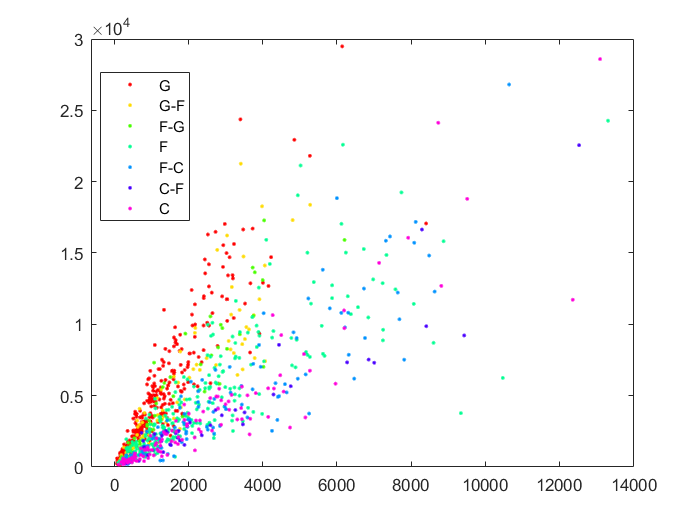

%boxplot(data.height,data.pos)
gscatter(data.rebounds,data.points,data.pos) % See the result. Is it meaningful? If not why?

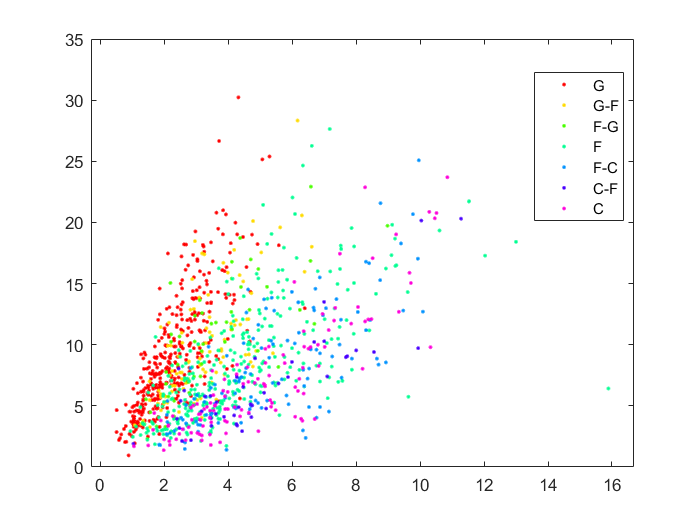

gscatter(data.rebounds./data.GP, data.points./data.GP , data.pos) % Divide by game played. Still linearly proportional

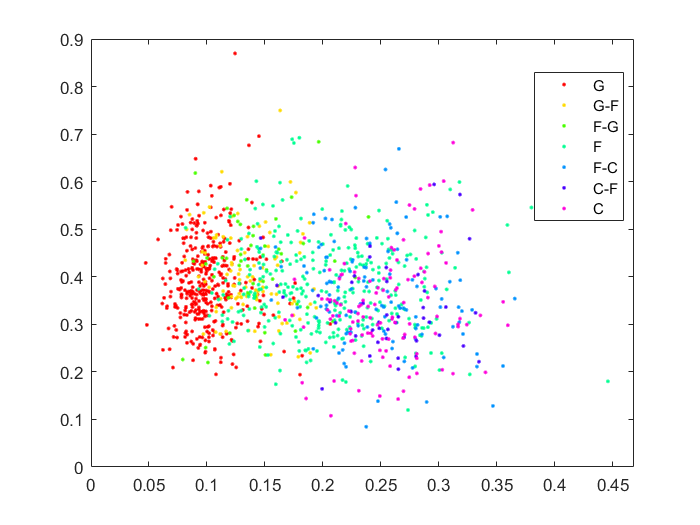

gscatter(data.rebounds./data.minutes, data.points./data.minutes , data.pos)% Divide by minutes played. Now data seems meaningful.

## Normalizing data - 정규화하는것. 

stats = data{:, 7:end};
statsnorm = bsxfun(@rdivide, stats , data.GP);
data{:, 7:end} = statsnorm;







